# Ejemplo desarrollo de intervalos basados en números difusos

## Cargar los datos entrada/salida

En este ejemplo se utilizaran datos entrada/salida generados a partir de la serie de chen.

clear
clc
load example_data.mat
f1 = figure(1);
t1 = tiledlayout('vertical');

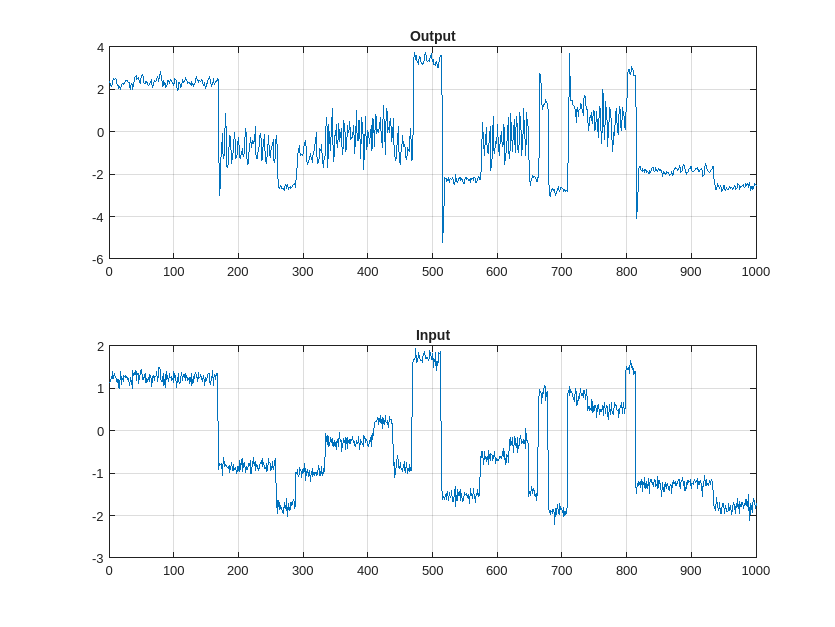

nexttile
plot(y(1:1000))
grid on
title('Output')

nexttile
plot(u(1:1000))
grid on
title('Input')

## Entrenar modelo difuso

Luego de obtener el numero optimo de regresores y clusters, se utiliza la funcion "`TakagiSugeno`" para entrenar un modelo difuso utilizando los datos del conjunto de entrenamiento.

optim_regs_y = [1 2];
optim_regs_u = [1 2];
clusters = 7;
TS_options = [1 2 1];
Z_ent_optim = [Y_reg.ent(:, optim_regs_y) U_reg.ent(:, optim_regs_u)];
[model, ~] = TakagiSugeno(Y.ent, Z_ent_optim, ...
    clusters, TS_options);

Luego, la variable `model` contiene toda la información para obtener predicciones con el modelo difuso

## Intervalo basado en numeros difusos

CP = 0.9;
[s_up, s_lw] = sintonizacion_fn(Y.ent, Y_reg.ent, U.ent, U_reg.ent, model, optim_regs_y, optim_regs_u, CP);

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 2 workers.

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100            4798            6172        0
    1             200            3881            5806        0
    2             300            2972            4852        0
    3             400            2839            4207        0
    4             500            2701            3689        0
    5             600            2616            3464        0
    6             700            2506            3309        0
    7             800            1926            2996        0
    8             900            1926            2829        1
    9            1000            1899            2649        0
   10            1100            1681            2422        0
   11            1200            1619            2266        0
   

## Calcular intervalos en conjunto de validación

% Prediccion valor esperado
Z_val_optim = [Y_reg.val(:, optim_regs_y) U_reg.val(:, optim_regs_u)];

Unable to resolve the name 'Y_reg.val'.

y_ts = ysim(Z_val_optim,model.a,model.b,model.g);

% Intervalos
[int_up, int_lw] = calc_intervals(Z_val_optim, model.a, model.b, s_up, s_lw);
y_up = y_ts + int_up;
y_lw = y_ts - int_lw;

## Graficos

A continuacion se grafican los resultados obtenidos

f = figure;
grid on
hold on

plot(Y.val, '.')
plot(y_ts, 'LineWidth',2)
plot(y_up, '-k')
plot(y_lw, '-k') % Para graficar un area revisar la funcion 'fill'
xlabel('Muestras')
ylabel('Salida')
xlim([1000 1500])
legend('Valor real', 'Prediccion', 'Location','best');
title(['RMSE = ' num2str(rmse(Y.val, y_ts))])